# Communication Theory AM Modulation

*Grafiklerin çizimi uzun sürebilir.

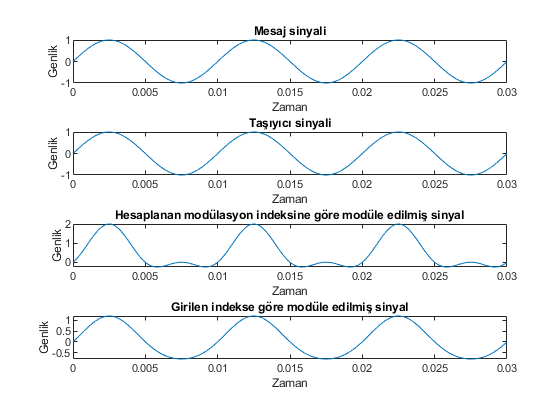

clear all;
clc;

Atasiyici=1;    % Taşıyıcı sinyalinin genliği
Amesaj=1;       % Mesaj sinyalinin genliği

ft=100;        % Taşıyıcı sinyalinin frekansı
fm=100;         % Mesaj sinyalinin frekansı

t=0.03;
t1=linspace(0,t,1000);

indekshesaplayici=Amesaj/Atasiyici;     % İndeks formülü
manuelgirilenindeks=0.2;                % Manuel indeks girişi

mesaj = sin(2*pi*fm*t1);                % Genliksiz yazılmış mesaj sinyali
tasiyici = sin(2*pi*ft*t1);             % Genliksiz yazılmış taşıyıcı sinyali

modulasyon = (1+indekshesaplayici.*mesaj).*(Atasiyici.*tasiyici);            % Modülasyon hesabı (İndekse dikkat)
manuelmodulasyon = (1+manuelgirilenindeks.*mesaj).*(Atasiyici.*tasiyici);    % Modülasyon hesabı (İndekse dikkat)
subplot(4,1,1)
plot(t1,mesaj)              % Mesaj sinyali
title('Mesaj sinyali')
xlabel('Zaman')
ylabel('Genlik')
subplot(4,1,2)
plot(t1,tasiyici)           % Taşıyıcı sinyali
title('Taşıyıcı sinyali')
xlabel('Zaman')
ylabel('Genlik')
subplot(4,1,3)
plot(t1,modulasyon)         % Modülasyon kısmına dikkat
title('Hesaplanan modülasyon indeksine göre modüle edilmiş sinyal')
xlabel('Zaman')
ylabel('Genlik')
subplot(4,1,4)
plot(t1,manuelmodulasyon)
title('Girilen indekse göre modüle edilmiş sinyal')
xlabel('Zaman')
ylabel('Genlik')